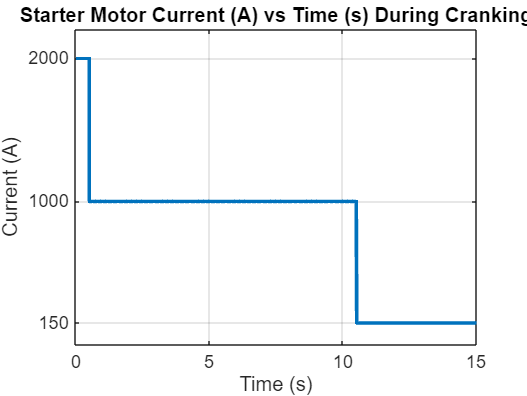

% Parameters
t_total = 15;        % Total time of simulation (seconds)
t_inrush_real = 0.05; % Real duration of inrush current (seconds)
t_inrush_vis = 0.5;     % Visualized duration of inrush (for plotting)
t_cranking = 10;      % Duration of cranking phase (seconds)

I_inrush = 2000;       % Inrush current (A)
I_cranking = 1000;     % Cranking current (A)
I_running = 150;       % Constant current after engine starts (A)

% Time vector for the "widened" inrush phase (first phase only)
t_inrush = linspace(0, t_inrush_vis, 300);  % Visualized inrush time (stretched)
I_inrush_phase = I_inrush * ones(size(t_inrush)); % Inrush current constant

% Time vector for the cranking and running phases (normal time scale)
t_cranking_phase = linspace(t_inrush_vis, t_total, 700);  % Rest of the time (cranking + running)
I_cranking_phase = zeros(size(t_cranking_phase));

for i = 1:length(t_cranking_phase)
    if t_cranking_phase(i) <= (t_inrush_vis + t_cranking)  % Cranking phase
        I_cranking_phase(i) = I_cranking;
    else  % Constant running current phase
        I_cranking_phase(i) = I_running;
    end
end

% Combine time and current vectors
t_combined = [t_inrush, t_cranking_phase];     % Time array with widened inrush
I_combined = [I_inrush_phase, I_cranking_phase];  % Current array

% Plotting the result
figure;
plot(t_combined, I_combined, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Current (A)');
title('Starter Motor Current (A) vs Time (s) During Cranking');
grid on;

% Set x and y axis limits
xlim([0 t_total]);       % Set x-axis from 0 to total simulation time
ylim([1 I_inrush * 1.1]);  % Set y-axis from 0 to 10% above inrush current
% Custom y-axis tick spacing
yticks([0 150 1000 2000]);  % Custom tick marks for y-axis